## Example Monthly Excess Returns

This version : 12/09/2024

## MSCI All-Country World Equity Index Historical Data  

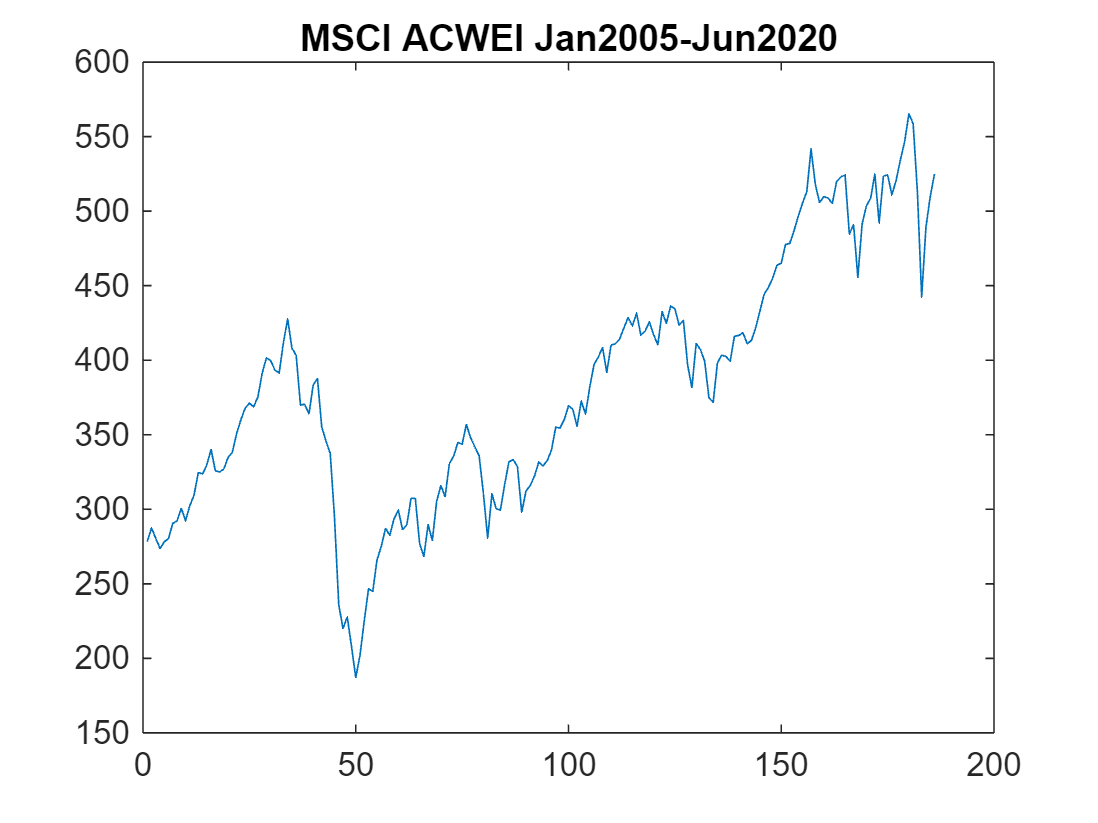

load Practice0Data.mat
%import data from current directory  monthly Jan2005-Jun2020
 
plot (price_msciw) 
title('MSCI ACWEI Jan2005-Jun2020');

NameVar='MSCI ACWEI';
[Table1] = DescriptiveTable(price_msciw,NameVar);

## S&P500 Index (^GSPC)

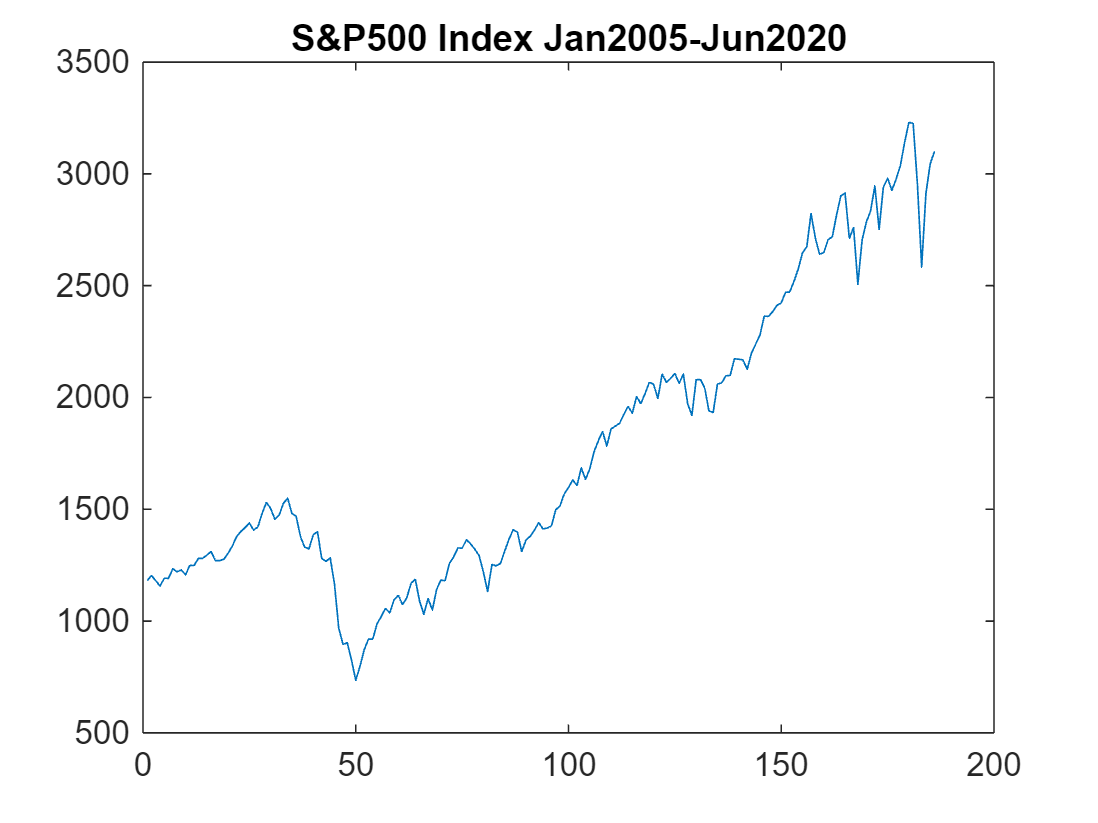

 
plot (price_sp500) 
title('S&P500 Index Jan2005-Jun2020');

## NASDAQ Composite (^IXIC)

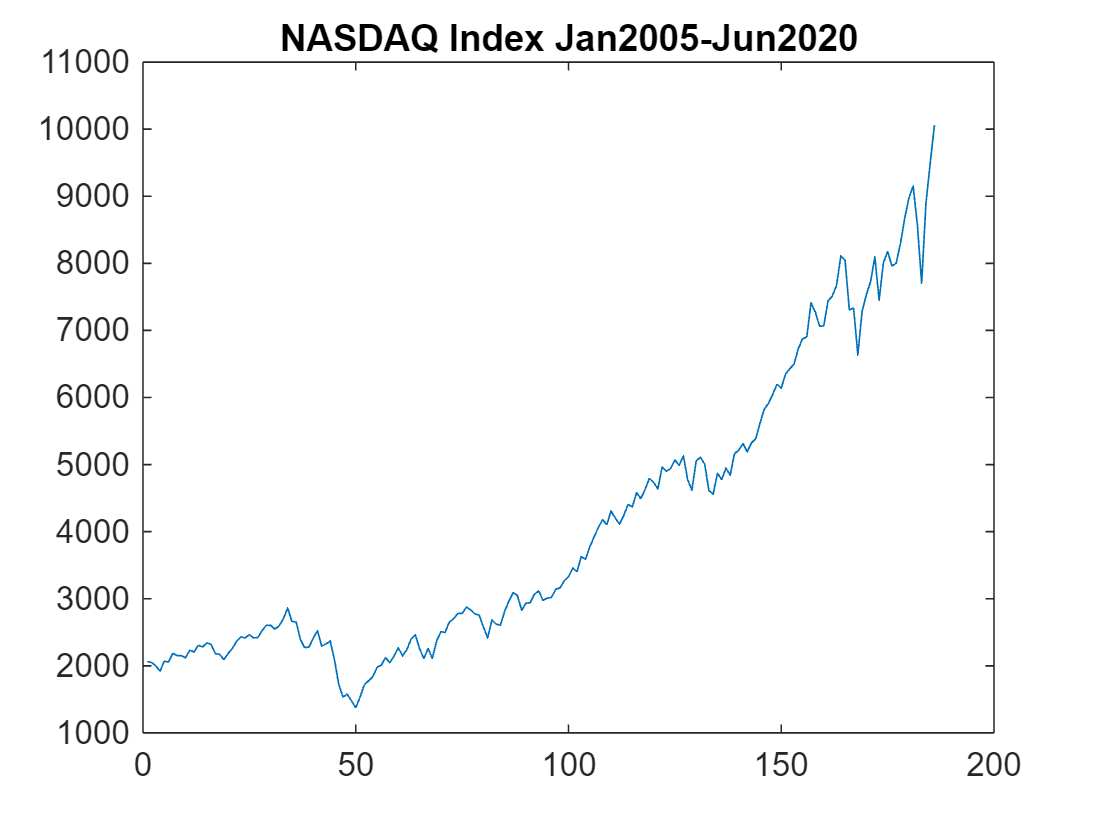


plot (price_na) 
title('NASDAQ Index Jan2005-Jun2020');

## 13 Week Treasury Bill Rate (^IRX)

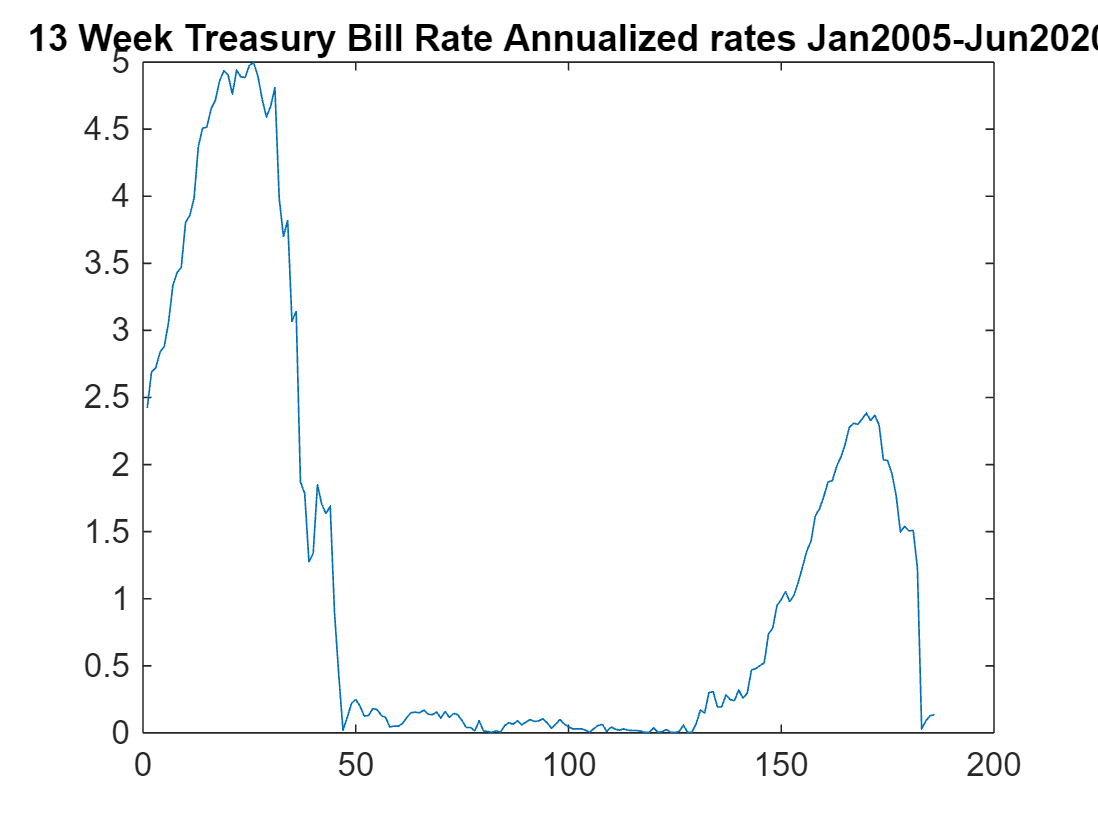




plot (rate_tb) 
title('13 Week Treasury Bill Rate Annualized rates Jan2005-Jun2020');

## Returns

Compute monthly excess returns  

e.g. exret_sp500 = r_sp500 - tb30/12

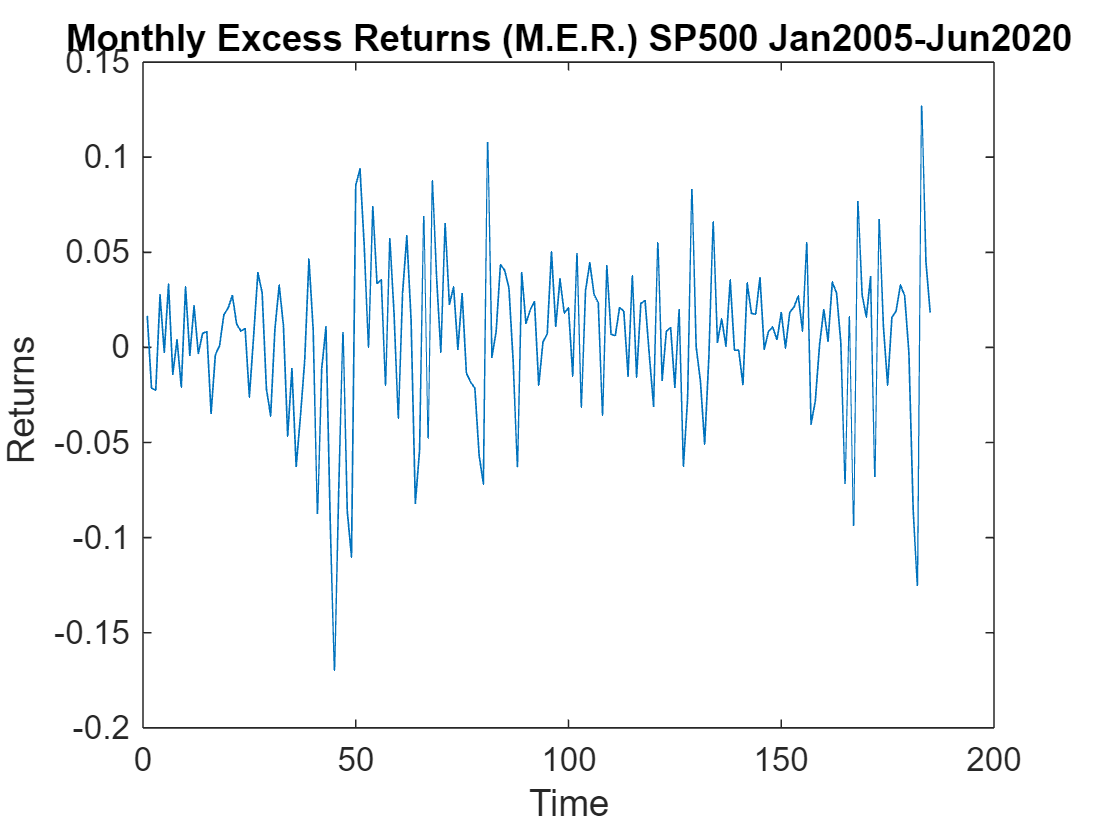

T=length(price_sp500);
r_sp500= price2ret(price_sp500,Method="periodic" );  % Monthly stock returns 
r_na=price2ret(price_na,Method="periodic" ); 
r_msciw= price2ret(price_msciw,Method="periodic" );
r_tb=(rate_tb/100)/12;                                   % monthly risk-free interest rates
% Monthly Excess returns
er_sp500 = r_sp500 - r_tb(2:T);                         
er_na = r_na - r_tb(2:T); 
er_msciw = r_msciw - r_tb(2:T); 

plot(er_sp500);
title('Monthly Excess Returns (M.E.R.) SP500 Jan2005-Jun2020');
ylabel('Returns ');
xlabel('Time');

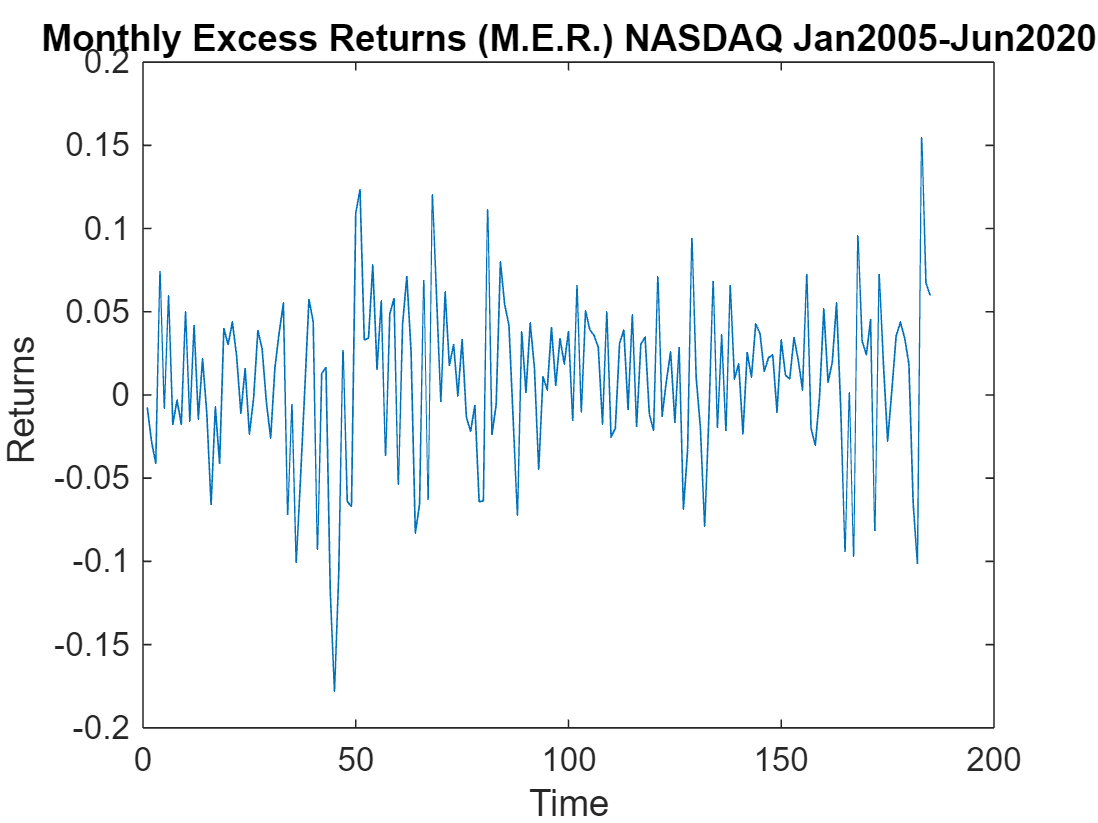

plot(er_na);
title('Monthly Excess Returns (M.E.R.) NASDAQ Jan2005-Jun2020');
ylabel('Returns ');
xlabel('Time');

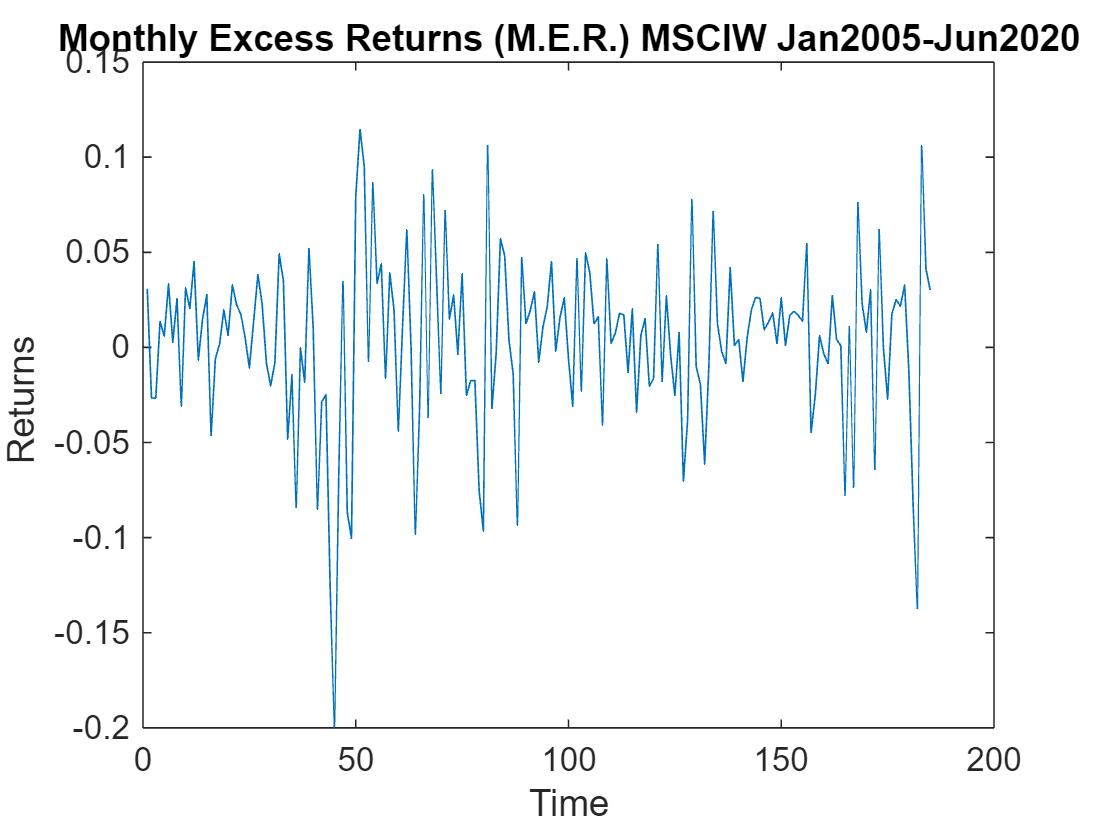

plot(er_msciw);
title('Monthly Excess Returns (M.E.R.) MSCIW Jan2005-Jun2020');
ylabel('Returns ');
xlabel('Time');

warning off


NameVar='M.E.R. SP500';
[Table1] = DescriptiveTable(er_sp500,NameVar)

Table1 = 1×8 table
                    Sample_Size      Mean         Max        Min         STD       Skewness    Kurtosis    JBPval
                    ___________    _________    _______    ________    ________    ________    ________    ______

    M.E.R. SP500        185        0.0050866    0.12677    -0.16979    0.042085    -0.71371     4.9276     0.001 


NameVar='M.E.R. Nasdaq';
[Table2] = DescriptiveTable(er_na,NameVar)

Table2 = 1×8 table
                     Sample_Size      Mean        Max        Min         STD       Skewness    Kurtosis    JBPval 
                     ___________    _________    ______    ________    ________    ________    ________    _______

    M.E.R. Nasdaq        185        0.0087874    0.1544    -0.17768    0.049438    -0.44495     3.9253     0.00862


NameVar='M.E.R. MSCIW';
[Table3] = DescriptiveTable(er_msciw,NameVar)

Table3 = 1×8 table
                    Sample_Size      Mean         Max        Min         STD       Skewness    Kurtosis    JBPval
                    ___________    _________    _______    ________    ________    ________    ________    ______

    M.E.R. MSCIW        185        0.0034481    0.11472    -0.19942    0.045334    -0.81693     5.3432     0.001 


TT=[Table1; Table2 ;Table3]

TT = 3×8 table
                     Sample_Size      Mean         Max        Min         STD       Skewness    Kurtosis    JBPval 
                     ___________    _________    _______    ________    ________    ________    ________    _______

    M.E.R. SP500         185        0.0050866    0.12677    -0.16979    0.042085    -0.71371     4.9276       0.001
    M.E.R. Nasdaq        185        0.0087874     0.1544    -0.17768    0.049438    -0.44495     3.9253     0.00862
    M.E.R. MSCIW         185        0.0034481    0.11472    -0.19942    0.045334    -0.81693     5.3432       0.001


## Local Functions

function [Table1] = DescriptiveTable(DatoX,NameVar)
    % Compute Table with Descriptive Statistics
    % 
Dyt=DatoX;
[h,lbqpal]=jbtest(Dyt);
TT=size(Dyt);
Table1=table(TT(1,1),mean(Dyt), max(Dyt),min(Dyt), std(Dyt),skewness(Dyt), kurtosis(Dyt), lbqpal);
Table1.Properties.VariableNames = {'Sample_Size','Mean','Max','Min', 'STD', 'Skewness', 'Kurtosis','JBPval'};
vr={NameVar};
Table1.Properties.RowNames = vr;

end